# Systemidentifikation aus Sprungantwort

#### IKA - Labortag - 19.05.2026

clearvars
close all
clc

### Daten laden

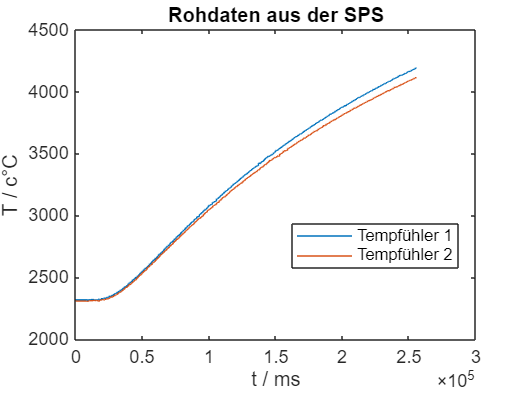

%file = "data/01_Volt1OhneVentilation.csv"
%file = "data/01_Volt2MitVentilation.csv"
file = "data/02_Volt1MitVentilation.csv";
%file = "data/02_Volt2MitVentilation10min.csv"

[t_ms, T_sps1, T_sps2, heating, U_in] = import_step_response(file);

plot(t_ms, T_sps1, t_ms, T_sps2)
xlabel("t / ms")
ylabel("T / c°C")
title("Rohdaten aus der SPS")
legend("Tempfühler 1", "Tempfühler 2", 'Location','best')

### Daten aufbereiten

- Temperaturen von c°C in °C umrechnen

- Durchschnittstemperature der beiden Sensoren bestimmen

- Zeit von ms in s umrechnen

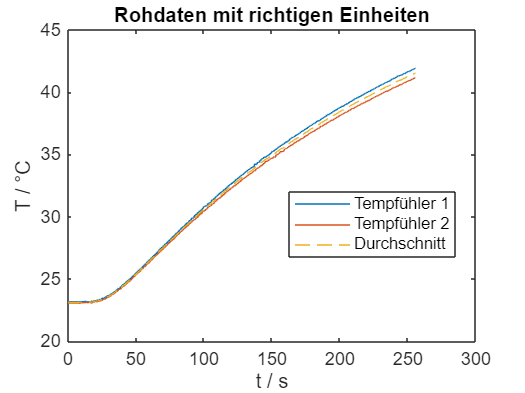

T_out1 = T_sps1 / 100;
T_out2 = T_sps2 / 100;
T_out = mean([T_out1, T_out2], 2);

t = t_ms / 1000;
t = t - t(1);
dt = t(2)-t(1);

plot(t, T_out1, t, T_out2, t, T_out, '--')
xlabel("t / s")
ylabel("T / °C")
title("Rohdaten mit richtigen Einheiten")
legend("Tempfühler 1", "Tempfühler 2", "Durchschnitt", 'Location','best')

### Zuschneiden der Daten auf Prozessstart

- Die Datenaufzeichnung beginnt vor dem aufbringen des Sprungs am Systemeingang

- Die Sprungantwort ist noch nicht ganz ein Einheitssprung, aber sehr knapp dran

- Wir können nicht auf eine absolute Temperatur regelen, da wir nur heizen, aber nicht kühlen können. Wir müssen also unsere Sprungantwort bei 0°C beginnen lassen indem wir die Starttemperatur abziehen.

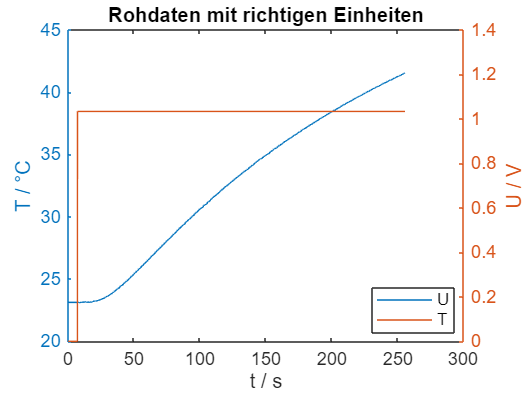

figure
yyaxis left
plot(t, T_out)
ylabel("T / °C")
yyaxis right
plot(t, heating .* U_in)
ylabel("U / V")

xlabel("t / s")
title("Rohdaten mit richtigen Einheiten")
legend("U", "T",'Location','best')

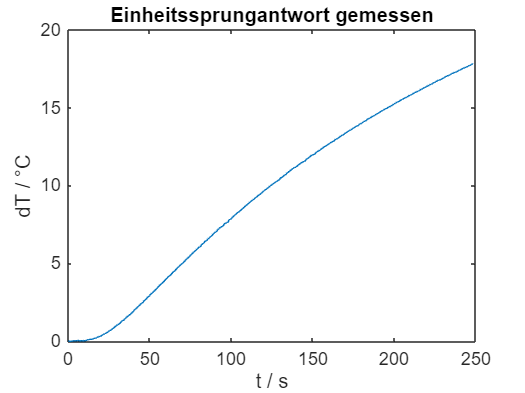

%Zuschneiden von U und T
[~, start_idx] = max(heating > 0);
T_out = T_out(start_idx:end);
U_in = U_in(start_idx:end);

t = t(1:size(T_out, 1));

%Normalisieren auf Einheitssprung
step_size = mean(U_in);
dT_out = T_out - T_out(1);
dT_out = dT_out / step_size;

figure
plot(t, dT_out);
xlabel("t / s")
ylabel("dT / °C")
title("Einheitssprungantwort gemessen")

### Systemidentifikation durchführen

- Bestimmen des zu erwarteten Systemtyps

- Automatisches Schätzen der Modellparameter K, tau, Tt

- Simulation in Simulink

options = optimoptions('lsqcurvefit', 'StepTolerance', 1e-15,'FunctionTolerance', 1e-15, 'MaxFunctionEvaluations', 4e3, 'MaxIterations', 1e3);

fit_function = @PT1T_fit;
param0 = [25, 250, 23];
param_lb = [18, 100, 10];
param_ub = [60, 500, 35];

%Automatisches Modell bestimmen
[param, rss] = lsqcurvefit(@(param, t0) fit_function(param, t0), param0, t, dT_out, param_lb, param_ub, options);


Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


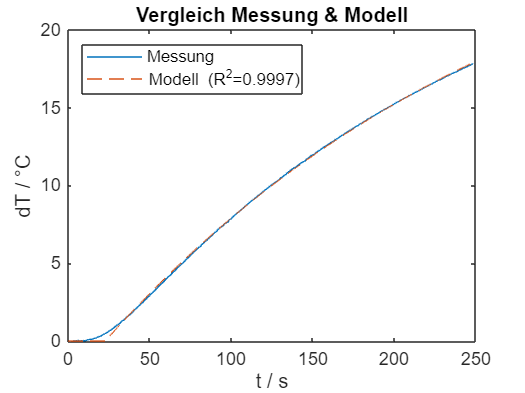

%K, tau, Tt

%Qualität des Modells bestimmen
[fit_data, G] = fit_function(param, t);
tss = sum((fit_data - mean(fit_data)).^2);
R_squared = 1 - (rss / tss);

plot(t, dT_out, t, fit_data, '--');
legend("Messung", ['Modell (R^2=', num2str(R_squared), ')'], "Location", "northwest")
xlabel("t / s")
ylabel("dT / °C")
title("Vergleich Messung & Modell")


G_zpk = zpk(G);
G_zpk.DisplayFormat = 'time constant'


G_zpk =
 
                 31.171
  exp(-23*s) * ----------
               (1+264.7s)
 
Continuous-time zero/pole/gain model.
Model Properties


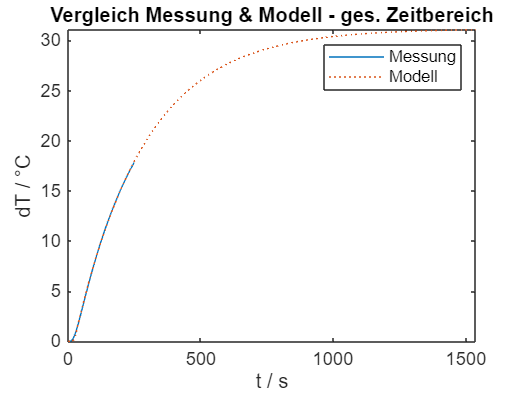


[G_data, G_t] = step(G_zpk);

plot(t, dT_out, G_t, G_data, ':');
ylim([0, inf])
xlabel("t / s")
ylabel("dT / °C")
title("Vergleich Messung & Modell - ges. Zeitbereich")
legend("Messung", "Modell")

### Reglerauslegung

- Auswahl eines Verfahrens --> T-Summen-Regel

%Aus automatischer Modellbildung
Ks = param(1);
tau = param(2);
Tt = param(3);

%Summenzeitkonstante bestimmen
T_sum = tau + Tt;

- Einstellregeln befolgen

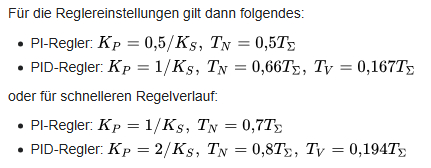

%PI - langsam
Kp_slow = 0.5 / Ks;
Tn_slow = 0.5 * T_sum;
Ki_slow = Kp_slow / Tn_slow;

%PI - schnell
Kp_fast = 1 / Ks;
Tn_fast = 0.7 * T_sum;
Ki_fast = Kp_fast / Tn_fast;

C_slow = pid(Kp_slow, Ki_slow)


C_slow =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.016, Ki = 0.000112
 
Continuous-time PI controller in parallel form.
Model Properties


C = pid(Kp_fast, Ki_fast)


C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.0321, Ki = 0.000159
 
Continuous-time PI controller in parallel form.
Model Properties


- Jetzt kann der Regler in Simulink getestet werden

open("temp_control_sim_simple.slx") 

### Performance

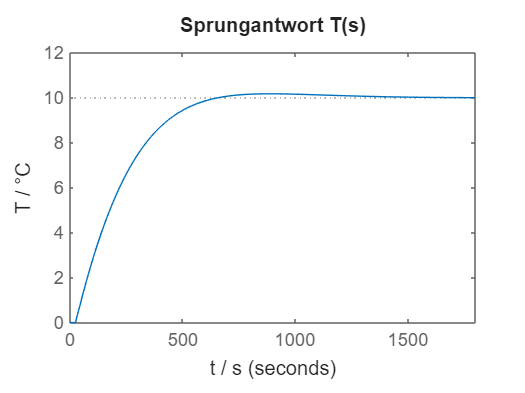

T_soll = 40;
T_umg = 30;
dT_step = T_soll - T_umg;

T = feedback(C*G, 1);

step(dT_step * T);
title("Sprungantwort T(s)")
xlabel("t / s")
ylabel("T / °C")

T_stepinfo = stepinfo(T)

T_stepinfo = struct with fields:
         RiseTime: 384.7907
    TransientTime: 579.8737
     SettlingTime: 579.8737
      SettlingMin: 0.9010
      SettlingMax: 1.0178
        Overshoot: 1.7792
       Undershoot: 0
             Peak: 1.0178
         PeakTime: 885.4060


System kann noch schneller gemacht werden!

- Wir erhöhen Kp und behalten Tn aus der T-Summenregel gleich

%PI - noch schneller!
e_max = 50 - 30; %50°C max Temp. bei Start mit 30°C
U_max = 4; %max Spannung von 4V die erreicht werden soll --> Puffer

Kp_max = U_max / e_max;
Ki_max = Ki_fast * (Kp_max / Kp_fast);

C_max = pid(Kp_max, Ki_max)


C_max =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.2, Ki = 0.000994
 
Continuous-time PI controller in parallel form.
Model Properties


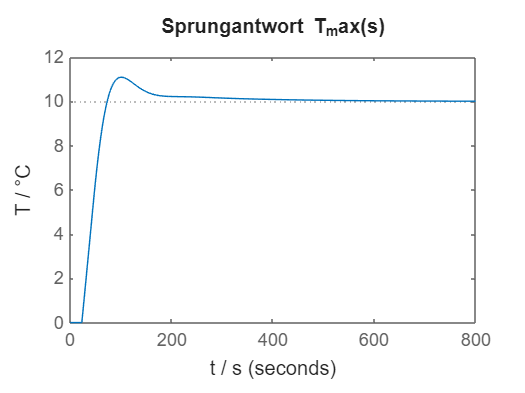


T_max = feedback(C_max*G, 1);

step(dT_step * T_max);
title("Sprungantwort T_max(s)")
xlabel("t / s")
ylabel("T / °C")

T_max_stepinfo = stepinfo(T_max)

T_max_stepinfo = struct with fields:
         RiseTime: 37.1568
    TransientTime: 249.9957
     SettlingTime: 249.9957
      SettlingMin: 0.9322
      SettlingMax: 1.1096
        Overshoot: 10.9647
       Undershoot: 0
             Peak: 1.1096
         PeakTime: 101.0779


### Evaluierung - Simulation vs. Implementierung

file_CL = "data/CL/3_PI_Stepresponse.csv";

%switched order!
[t_ms_CL, T_sps1_CL, T_sps2_CL, U_in_CL, heating_CL] = import_step_response(file_CL);

t_CL = t_ms_CL / 1000;
t_CL = t_CL - t_CL(1);
dt_CL = t_CL(2)-t_CL(1);

T_out1_CL = T_sps1_CL / 100;
T_out2_CL = T_sps2_CL / 100;
T_out_CL = mean([T_out1_CL, T_out2_CL], 2);

%
[~, start_idx_CL] = max(heating_CL > 0);
T_out_CL = T_out_CL(start_idx_CL:end);
U_in_CL = U_in_CL(start_idx_CL:end);

dT_out_CL = T_out_CL - T_out_CL(1);
t_CL = t_CL(1:size(T_out_CL, 1));

%
T_start_CL = 30;
T_soll_CL = 40.06;
dT_step_CL = T_soll_CL - T_start_CL;

dT_out_CL_sim = step(dT_step_CL * T_max, t_CL);

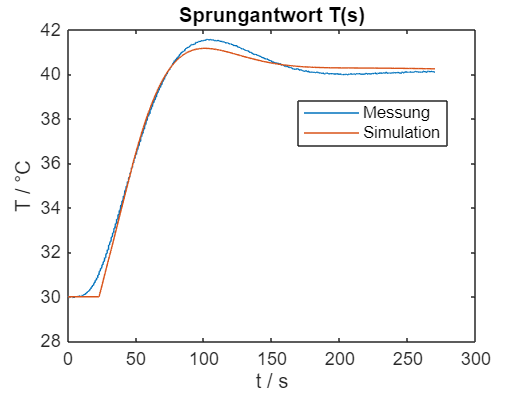

plot(t_CL, dT_out_CL + T_start_CL, t_CL, dT_out_CL_sim + T_start_CL)
title("Sprungantwort T(s)")
xlabel("t / s")
ylabel("T / °C")
legend("Messung", "Simulation", 'Location', 'best');